Load data

clear
I = zeros([19200 , 16],"double");
for i = 1:16
    im = imread("fruits/image_" + string(i) + ".png");
    I(:,i) = reshape(im,[19200, 1]);
    I(:,i) = rescale(I(:,i));
end

finding the eigen faces

me = (sum(I,2)/size(I,2));
I = I - me;
co = I'*I / size(I,2); %covariance matrix
[u, s] = svd(co); % u=eigen vectors, diag(s)= eigenvalues
u =  I * u ;
u = normc(u);


images and plots for eigenvalues and mean

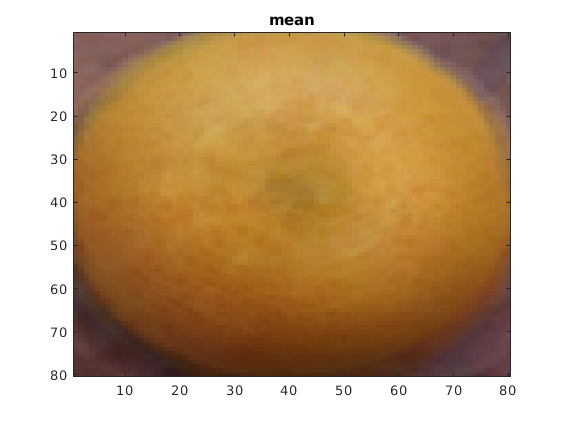

figure
imagesc(reshape(me,[80, 80, 3]))
title("mean")

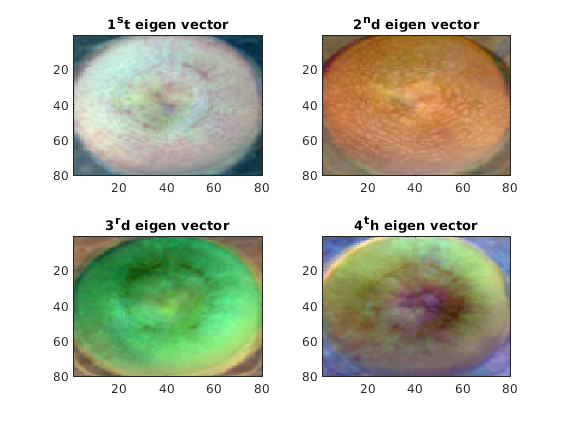

figure
subplot(2,2,1), imagesc(rescale(reshape(u(:,1),[80, 80, 3])))
title("1^st eigen vector")
subplot(2,2,2), imagesc(rescale(reshape(u(:,2),[80, 80, 3])))
title("2^nd eigen vector")
subplot(2,2,3), imagesc(rescale(reshape(u(:,3),[80, 80, 3])))
title("3^rd eigen vector")
subplot(2,2,4), imagesc(rescale(reshape(u(:,4),[80, 80, 3])))
title("4^th eigen vector")

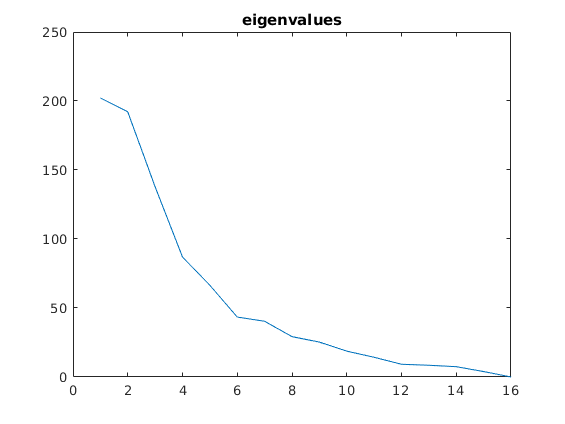

figure
plot(diag(s))
title("eigenvalues")

projection

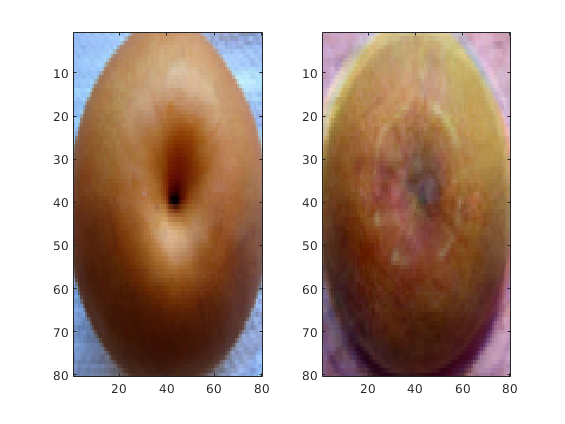

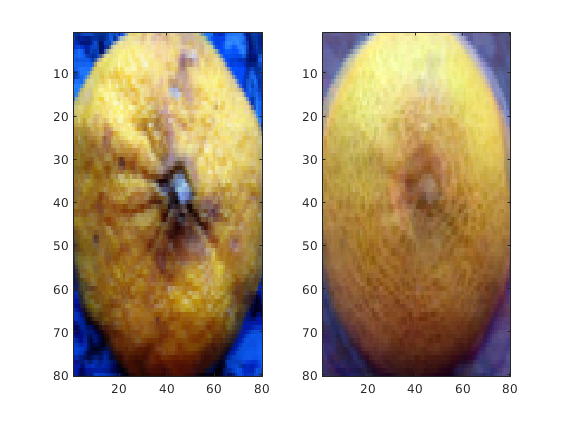

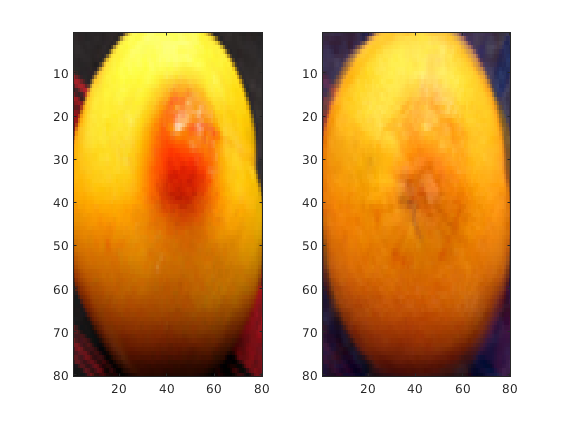

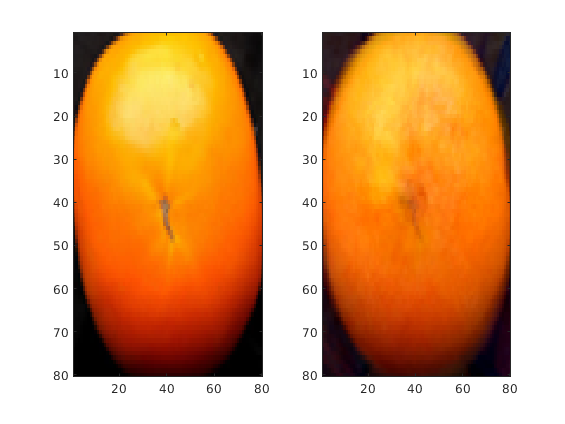

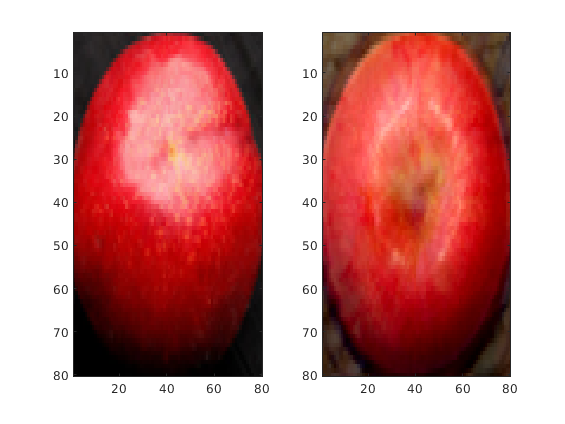

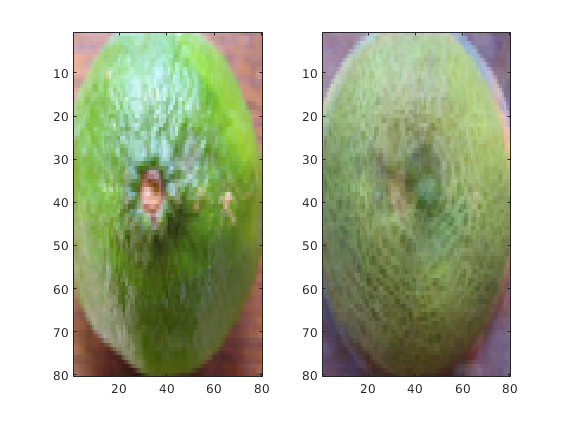

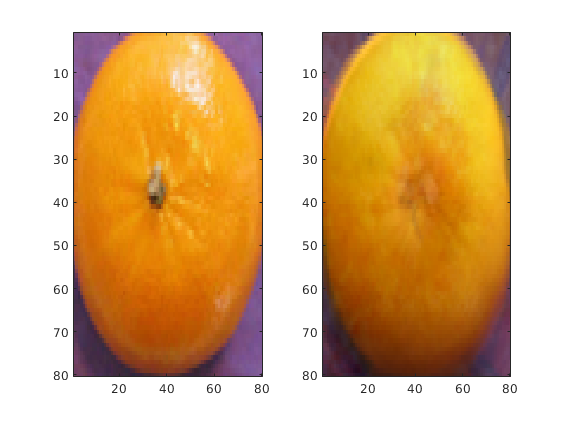

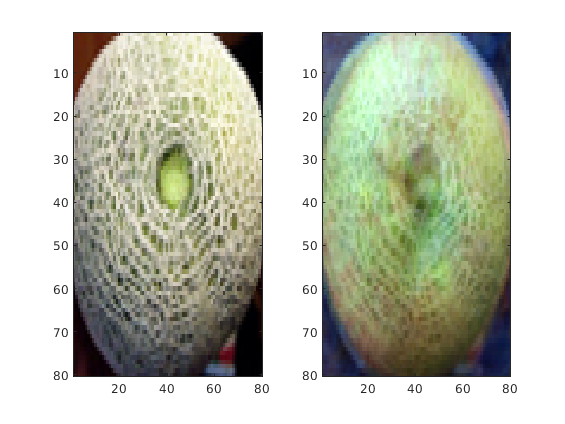

weights = ones([5,16]);
weights(1:4,:) = u(:,1:4)' * I;
re_I = u(:,1:4)*weights(1:4,:)+me;
for i=1:16
    figure
    subplot(1,2,1), imagesc(reshape(I(:,i)+me,[80, 80,3]))
    subplot(1,2,2), imagesc(reshape(re_I(:,i),[80, 80,3]))
end

Random Fruits from normal distribution

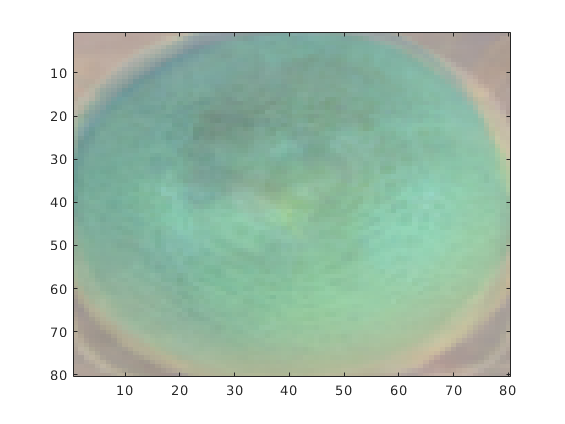

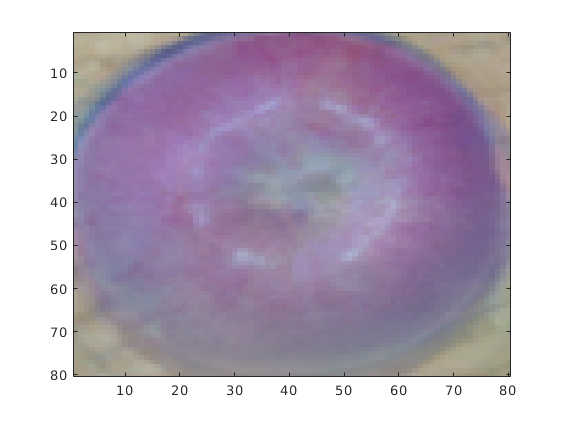

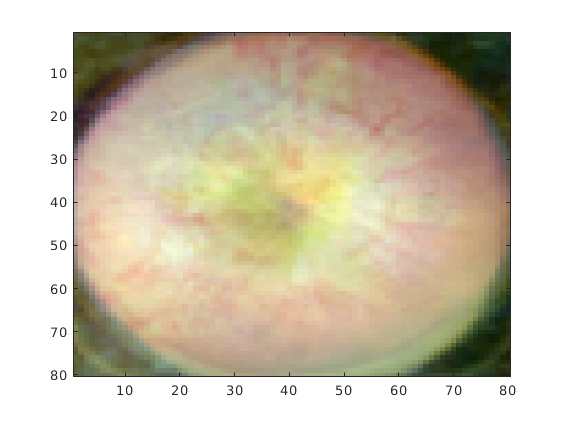

w = randn([4, 3]) * 100;
w = w + randn([1,3]);
new_f = rescale(u(:,1:4)*w + me);
for i= 1:3
    figure
    imagesc(reshape(new_f(:,i),[80, 80,3]))
end